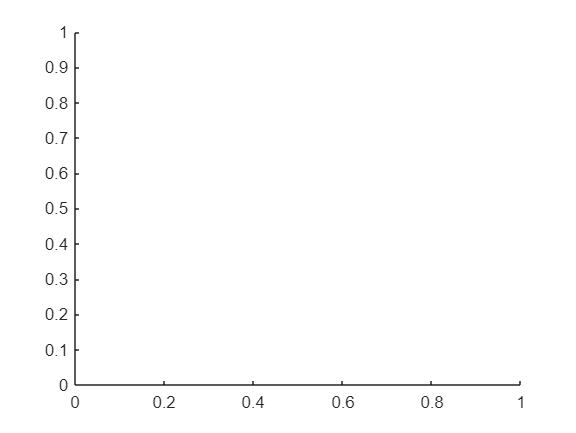

clear all
clc
hold on

%Definición parámetros del módulo, en este caso del PWP201

Voc=16.799;
Isc=1.0317;
Imp=0.92550;
Vmp=12.4929;
T=45;
Ns=36;
G=1000;
Ie= transpose(xlsread('PWP201.xlsx','C3:C25'));
Ve= transpose(xlsread('PWP201.xlsx','B3:B25'));

%constantes físicas
q=1.60218*10^(-19);
K=1.38065*10^(-23);
%Calculo Vth por Ns
Vth=Ns*K*(T+273.15)/q;
%Valor de n fijo en función de la tecnología
n=1.11;
%definición valores iniciales
Rs=0;
Iph=Isc; 
err=10;
Rsh=Vmp/(Isc-Imp)-(Voc-Vmp)/Imp %Rsh,min

Rsh =    1.1298e+02


err=10;
itt=0;
Pm=Imp*Vmp;
%Ajuste de los valores de tensión RTC es el siguiente
V=(Vmp):0.001:Voc;
%Ajuste de los valores de tensión de los demás módulos
V=(Vmp-1):0.1:(Voc+1);
Pmax=Imp*Vmp

Pmax =    1.1562e+01


dRs=0.01;
%% Iteration
iter=0;
Io=(Isc)/(exp((Voc)/(n*Vth))-1)

Io =    2.2600e-07


while err>0.0001
    Iph=(Rsh+Rs)/Rsh*Isc;
    Rsh=Vmp*(Vmp+Imp*Rs)/(Vmp*Iph-Vmp*Io*(exp((Vmp+Rs*Imp)/(n*Vth)))+Vmp*Io-Pmax)
    for i=1:length(V)
       clear I
        syms I
        eqn=I==Iph-Io*(exp((V(i)+I*Rs)/(n*Vth))-1)-(V(i)+I*Rs)/Rsh;
        Iol=vpasolve(eqn,I);
        Isol(i)=double(Iol);
    end
    P=V.*Isol;
    Pe=max(P);
    err=100*abs((Pe-Pmax)/Pmax);
    %ajuste en caso del RTC
    %DRs=err/100;
    %ajuste en los demás casos de los incrementos de Rs
    DRs=err/10;
    Rs=Rs+DRs;
    iter=iter+1;
end

Rsh =    1.4536e+02


Rsh =    1.5886e+02


Rsh =    1.7307e+02


Rsh =    1.8748e+02


Rsh =    2.0174e+02


Rsh =    2.1575e+02


Rsh =    2.2940e+02


Rsh =    2.4254e+02


Rsh =    2.5535e+02


Rsh =    2.6773e+02


Rsh =    2.7949e+02


Rsh =    2.9101e+02


Rsh =    3.0221e+02


Rsh =    3.1297e+02


Rsh =    3.2322e+02


Rsh =    3.3294e+02


Rsh =    3.4246e+02


Rsh =    3.5180e+02


Rsh =    3.6091e+02


Rsh =    3.6976e+02


Rsh =    3.7833e+02


Rsh =    3.8659e+02


Rsh =    3.9451e+02


Rsh =    4.0208e+02


Rsh =    4.0929e+02


Rsh =    4.1613e+02


Rsh =    4.2260e+02


Rsh =    4.2881e+02


Rsh =    4.3492e+02


Rsh =    4.4097e+02


Rsh =    4.4693e+02


Rsh =    4.5281e+02


Rsh =    4.5861e+02


Rsh =    4.6431e+02


Rsh =    4.6991e+02


Rsh =    4.7542e+02


Rsh =    4.8082e+02


Rsh =    4.8611e+02


Rsh =    4.9130e+02


Rsh =    4.9637e+02


Rsh =    5.0133e+02


Rsh =    5.0618e+02


Rsh =    5.1090e+02


Rsh =    5.1551e+02


Rsh =    5.2000e+02


Rsh =    5.2437e+02


Rsh =    5.2862e+02


Rsh =    5.3276e+02


Rsh =    5.3677e+02


Rsh =    5.4067e+02


Rsh =    5.4444e+02


Rsh =    5.4811e+02


Rsh =    5.5165e+02


Rsh =    5.5509e+02


Rsh =    5.5841e+02


Rsh =    5.6162e+02


Rsh =    5.6473e+02


Rsh =    5.6773e+02


Rsh =    5.7062e+02


Rsh =    5.7341e+02


Rsh =    5.7611e+02


Rsh =    5.7870e+02


Rsh =    5.8120e+02


Rsh =    5.8361e+02


Rsh =    5.8593e+02


Rsh =    5.8816e+02


Rsh =    5.9031e+02


Rsh =    5.9237e+02


Rsh =    5.9435e+02


Rsh =    5.9626e+02


Rsh =    5.9809e+02


Rsh =    5.9984e+02


Rsh =    6.0153e+02


Rsh =    6.0315e+02


Rsh =    6.0470e+02


Rsh =    6.0619e+02


Rsh =    6.0762e+02


Rsh =    6.0899e+02


Rsh =    6.1030e+02


Rsh =    6.1155e+02


Rsh =    6.1276e+02


Rsh =    6.1391e+02


Rsh =    6.1501e+02


Rsh =    6.1607e+02


Rsh =    6.1708e+02


Rsh =    6.1805e+02


Rsh =    6.1898e+02


Rsh =    6.1986e+02


Rsh =    6.2071e+02


Rsh =    6.2152e+02


Rsh =    6.2230e+02


Rsh =    6.2304e+02


Rsh =    6.2374e+02


Rsh =    6.2442e+02


Rsh =    6.2507e+02


Rsh =    6.2569e+02


Rsh =    6.2628e+02


Rsh =    6.2684e+02


Rsh =    6.2738e+02


Rsh =    6.2790e+02


Rsh =    6.2839e+02


Rsh =    6.2886e+02


Rsh =    6.2931e+02


Rsh =    6.2974e+02


Rsh =    6.3015e+02


Rsh =    6.3054e+02


Rsh =    6.3091e+02


Rsh =    6.3127e+02


Rsh =    6.3161e+02


Rsh =    6.3193e+02


Rsh =    6.3224e+02


Rsh =    6.3254e+02


Rsh =    6.3282e+02


Rsh =    6.3309e+02


Rsh =    6.3335e+02


Rsh =    6.3359e+02


Rsh =    6.3383e+02


Rsh =    6.3405e+02


Rsh =    6.3426e+02


Rsh =    6.3447e+02


Rsh =    6.3466e+02


Rsh =    6.3485e+02


Rsh =    6.3502e+02


Rsh =    6.3519e+02


Rsh =    6.3535e+02


Rsh =    6.3550e+02


Rsh =    6.3565e+02


Rsh =    6.3579e+02


Rsh =    6.3592e+02


Rsh =    6.3605e+02


Rsh =    6.3617e+02


Rsh =    6.3629e+02


Rsh =    6.3640e+02


Rsh =    6.3650e+02


Rsh =    6.3660e+02


Rsh =    6.3670e+02


Rsh =    6.3679e+02


Rsh =    6.3688e+02


Rsh =    6.3696e+02


Rsh =    6.3704e+02


Rsh =    6.3711e+02


Rsh =    6.3718e+02


Rsh =    6.3725e+02


Rsh =    6.3732e+02


Rsh =    6.3738e+02


Rsh =    6.3744e+02


Rsh =    6.3750e+02


Rsh =    6.3755e+02


Rsh =    6.3760e+02


Rsh =    6.3765e+02


Rsh =    6.3770e+02


Rsh =    6.3774e+02


Rsh =    6.3779e+02


Rsh =    6.3783e+02


Rsh =    6.3786e+02


Rsh =    6.3790e+02


Rsh =    6.3794e+02


Rsh =    6.3797e+02


Rsh =    6.3800e+02


Rsh =    6.3803e+02


Rsh =    6.3806e+02


Rsh =    6.3809e+02


Rsh =    6.3812e+02


Rsh =    6.3814e+02


Rsh

Rsh =    6.3814e+02


Rs

Rs =    1.7241e+00


Iph

Iph =    1.0345e+00


n

n =    1.1100e+00


Io

Io =    2.2600e-07


iter

iter =    164


err

err =    9.8549e-05


%calculo puntos curva I-V con los parámetros obtenidos
for i=1:length(Ve)
    clear I
    syms I 
    eqn=0==-I+Iph-Io*(exp((Ve(i)+I*Rs)/(n*Vth))-1)-((Ve(i)+I*Rs)/Rsh);
    Iol=vpasolve(eqn,I);
    Is(i)=double(Iol);
    err(i)=100*abs((Is(i)-Ie(i))/Ie(i));
end
%obtención del RMSE
RMSE=rmse(Is,Ie)/Isc*100

RMSE =    1.2323e+00
